clc,clear
% %优化
%给出0.5的结果 其他列表？ 如果结果一样则没必要
beta=0.5;
flag=1;
r=ca_diff_beta(beta,flag);

r

r =     0.6000    0.1745    0.1745    0.0303


clc,clear
result=[];
for beta=0.1:0.1:1
    r=ca_diff_beta(beta,[]);
    result=[result;r];
end
% 创建一个矩阵
data=result;
% 保存数据到Excel文件
filename = 'result.xlsx';
sheet = 'Sheet1';
xlswrite(filename, data, sheet);

data=csvread("result.csv")

data =     0.6000    0.1745    0.1745    0.0299
    0.6000    0.1745    0.1745    0.0301
    0.6000    0.1745    0.1745    0.0302
    0.6000    0.1745    0.1745    0.0303
    0.6000    0.1745    0.1745    0.0303
    0.6000    0.1745    0.1745    0.0303
    0.6000    0.1745    0.1745    0.0303
    0.6000    0.1745    0.1745    0.0304
    0.6000    0.1745    0.1745    0.0304
    0.6000    0.1745    0.1745    0.0304


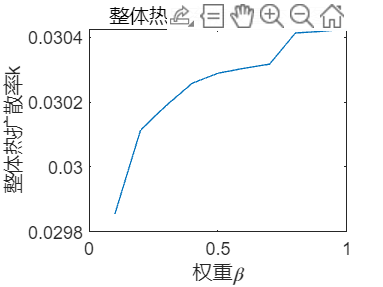

plot(0.1:0.1:1,data(:,4))
title("整体热导率随权重变化图")
xlabel('权重\beta')
ylabel('整体热扩散率k')

function result=ca_diff_beta(beta,flag)
 options=[];
 narvs = 4;
 x_lb=[10,10]./360*2*pi;  %单位 rad
 x_lb=[0.3,x_lb,0];
 x_ub=[26.565,26.565]./360*2*pi;
 x_ub=[0.6,x_ub,0.1];
 if flag==1
    options = optimoptions('particleswarm','MaxIterations',800,'Display','iter','PlotFcn','pswplotbestf','HybridFcn',@fmincon);  
    [x,~,~,~] = particleswarm(@(c)Obj_fun(c,beta), narvs, x_lb, x_ub,options); 
 else
 %options = optimoptions('particleswarm','MaxIterations',800);   
    [x,~,~,~] = particleswarm(@(c)Obj_fun(c,beta), narvs, x_lb, x_ub);   
 end
result=x;
end
function f=Obj_fun(parameter,beta)
    %initialize parameter
    d=parameter(1);                                    %单根纤维的直径  mm 
    h=2*d;                                    %织物的厚度  mm
    T_end=0.1;                          
    m = 0;              
    x = linspace(0,h,50);                     %单位 mm
    t =linspace(0,T_end,50);                  %单位s
    flag=1;
    sol = pdepe(m,@(x,t,u,dudt)pdex1pde(x,t,u,dudt,parameter,flag),@pdex1ic,@(xl,ul,xr,ur,t) ...
        pdex1bc(xl,ul,xr,ur,t,parameter) ,x,t);
    u_d_theta = sol(:,:,1);
    flag=0;
    sol = pdepe(m,@(x,t,u,dudt)pdex1pde(x,t,u,dudt,parameter,flag),@pdex1ic,@(xl,ul,xr,ur,t) ...
        pdex1bc(xl,ul,xr,ur,t,parameter),x,t);
    u_k = sol(:,:,1);
    f=(1-beta)*parameter(4)+beta*sum(sum(abs(u_k-u_d_theta))/2500);
end
function [c,f,s] = pdex1pde(x,t,u,dudx,parameter,flag)
    k_fiber=0.0437;                             %纤维热导率
    cp=0.05;                                    %单位  Mj/m^3·K
    k_air=0.0296;                               %单位 W/(m·K)
    d=parameter(1);      
    theta_s=parameter(2);                       %经纱弯曲角度 rad
    theta_w=parameter(3);                       %纬纱弯曲角度 rad
    a=d/tan(theta_s);                           %1/rho_s       
    b=d/tan(theta_w);                           %1/rho_w        
    S=a*b;                                      %单位 mm^2     
    S2=ca_S(x,d,theta_s,theta_w);       
    S1=S-S2;        
    if flag==1
     k_tol=(S1*k_air+S2*k_fiber)/S;              %截面热导率
    else
        k_tol=parameter(4);
    end
    c=cp;
    f =k_tol*dudx;
    s=0;
end
function S=ca_S(h,d,theta_s,theta_w)  
    if h>=d
        h=2*d-h;
    end
    if h<=d/2
    l=sqrt((d/2)^2-(d/2-h)^2);                  %弦长
    thetas=asin(l/(d/2));
    S_s=pi*(d/2)^2*thetas/pi-1/2*(d/2)^2*sin(2*thetas);
    thetaw=asin(l/(d/2));
    S_w=pi*(d/2)^2*thetaw/pi-1/2*(d/2)^2*sin(2*thetaw);
    S=(S_w/tan(theta_w)+S_s/tan(theta_s));
    elseif h>d/2
    theta_s=19.8/360*2*pi;                      %经纱弯曲角度 rad
    theta_w=25.64/360*2*pi;                     %纬纱弯曲角度 rad
    l=sqrt((d/2)^2-(d/2-h)^2);                  %弦长
    thetas=asin(l/(d/2));
    S_s=pi*(d/2)^2*thetas/pi-1/2*(d/2)^2*sin(2*thetas);
    S_s=pi*(d/2)^2-S_s;
    thetaw=asin(l/(d/2));
    S_w=pi*(d/2)^2*thetaw/pi-1/2*(d/2)^2*sin(2*thetaw);
    S_w=pi*(d/2)^2-S_w;
    S=(S_w/tan(theta_w)+S_s/tan(theta_s));
    end
end
function u0 = pdex1ic(x)
    u0 = 298.15;
end
function [pl,ql,pr,qr] = pdex1bc(xl,ul,xr,ur,t,c)   
    d=c(1);
    dT=0.9708905105832;
    pl=(0.033*dT)/(2*d); 
    ql =0.0296;
    pr = 0;
    qr = 1;
end
function u=L_Tight(t)
  p=[-59599.9047557005	14375.0113350970	-1218.80638780507	47.3729535516151	298.152007531907];
  u = p(1).*t.^4 + p(2).*t.^3 + p(3).*t.^2 + p(4).*t + p(5);
end
